clear all
opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [9, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Node", "Nominal_stress", "X_heigth", "Ymm", "Var5"];
opts.SelectedVariableNames = ["Node", "Nominal_stress", "X_heigth", "Ymm"];
opts.VariableTypes = ["double", "double", "double", "double", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Var5", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var5", "EmptyFieldRule", "auto");

% Import the data
tbl = readtable("Stress_data.csv", opts);


data = table2array(tbl)

data =             1          3.4         3.75        45.77
            2          3.2       3.6875        45.77
            3            3        3.625        45.77
            4          2.8       3.5625        45.77
            5          2.6          3.5        45.77
            6          2.5       3.4375        45.77
            7          2.3        3.375        45.77
            8          2.2       3.3125        45.77
            9          2.1         3.25        45.77
           10            2       3.1875        45.77


Y_data = data(:,4)

Y_data =         45.77
        45.77
        45.77
        45.77
        45.77
        45.77
        45.77
        45.77
        45.77
        45.77



% data3 = data((data(:,1)<N_D) && (data(:,3)==0))


Jeg sortere dataen så kun det der ligger præcis på linjen kommer med (45,77).

data_sort = [];
Y_line = 45.77

Y_line =         45.77


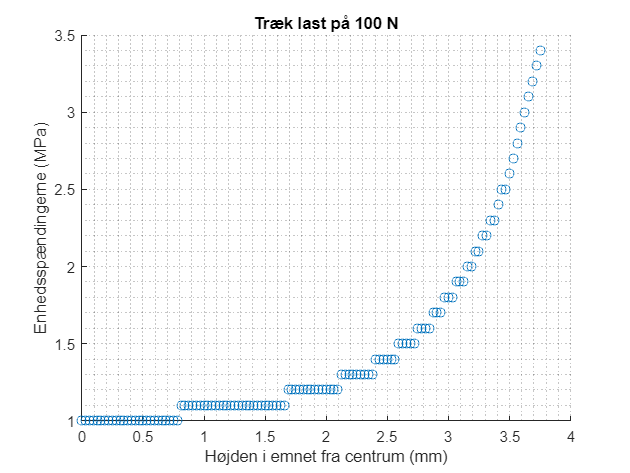


for i = 1:length(data(:,1))
    if Y_data(i) == Y_line
        data_sort(end+1,2:3) = data(i,2:3);
    end
end


sigma = data_sort(:,2);
x = data_sort(:,3);

scatter(x, sigma)
% plot(x, sigma)
title('Træk last på 100 N')
xlabel("Højden i emnet fra centrum (mm)")
ylabel("Enhedsspændingerne (MPa)")
grid('minor')

F = 100; %N
A = pi*max(x)^2; % normal arealet på kraften
sigma_k = sigma %Fe spændingerne

sigma_k =           3.4
          3.2
            3
          2.8
          2.6
          2.5
          2.3
          2.2
          2.1
            2


sigma_n = F/A

sigma_n =        2.2635



K_t = sigma_k/sigma_n

K_t =        1.5021
       1.4137
       1.3254
        1.237
       1.1486
       1.1045
       1.0161
      0.97193
      0.92775
      0.88357


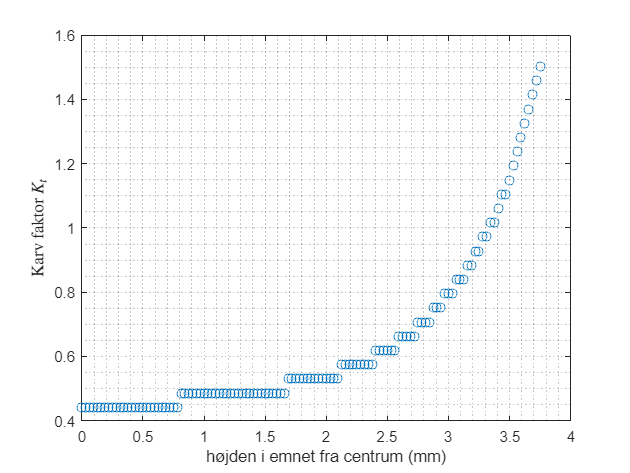

plot(x,K_t, 'o')
xlabel("højden i emnet fra centrum (mm)")
ylabel("Karv faktor $K_t$", Interpreter='latex')
grid('minor')


$$\chi^* = \left| \frac{\Delta\sigma}{\sigma_{k,max} \Delta x} \right|$$


% sigma_1_k = sigma(1)
dx = x(1) - x(2) % mindre x skridt afstand

dx =        0.0625


dS = sigma(1)/sigma(2)

dS =        1.0625


sigma(1)/max(sigma_k)

ans =      1


sigma(2)/max(sigma_k)

ans =       0.94118


X_grad = (sigma(1)/max(sigma_k) - sigma(2)/max(sigma_k))/((x(1) - x(2)))

X_grad =       0.94118


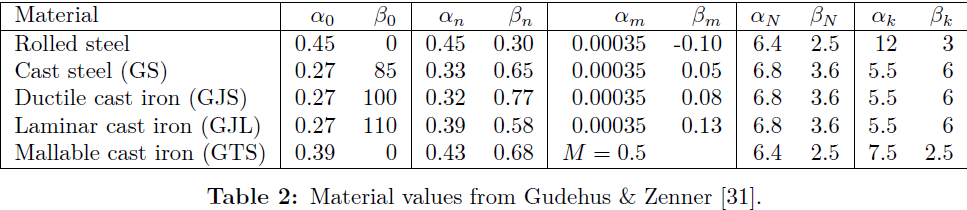

alpha_n = 0.32; 
beta_n = 0.77;
n = 1 + alpha_n * X_grad^beta_n

n =        1.3054


K_f = max(K_t)/n

K_f =        1.1507


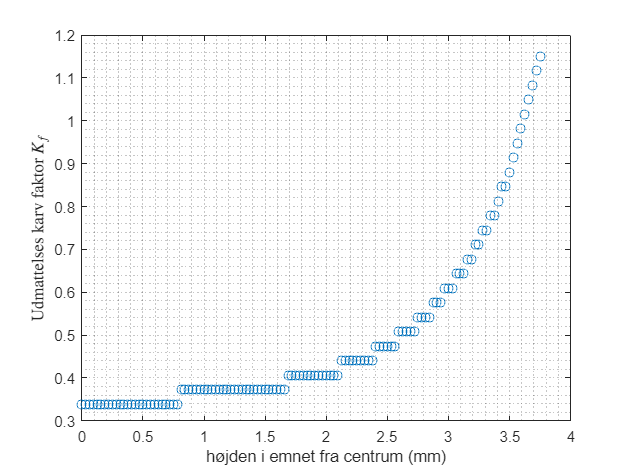

K_fs = K_t/n;
plot(x,K_fs, 'o')
xlabel("højden i emnet fra centrum (mm)")
ylabel("Udmattelses karv faktor $K_f$", Interpreter='latex')
grid('minor')

sigma_R_smooth = 104.5 % MPa (for 𝑁𝐷=106 cycles).

sigma_R_smooth =         104.5


sigma_R_notched = sigma_R_smooth/max(K_f)

sigma_R_notched =        90.818


sigma_R_notched_real = 79.8; %MPa
procent_afvigelse = (sigma_R_notched - sigma_R_notched_real)/sigma_R_notched

procent_afvigelse =       0.12132


K_f_real = sigma_R_smooth/sigma_R_notched_real

K_f_real =        1.3095


n_real = max(K_t)/K_f_real

n_real =         1.147


n

n =        1.3054


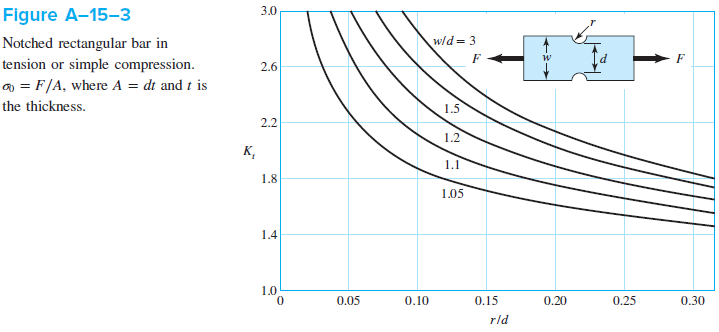

r = 2.25; %mm
d = 7.5; %mm
D = 12; %mm
% a = 0.2;%0.46^2
Rm = 500; %MPa
a_sqrt = 1.24-0.00225*Rm+0.0000016*Rm^2 - 0.000000000411*Rm^3

a_sqrt =       0.46362


a = a_sqrt^2

a =       0.21495


q = 1 / (1 + sqrt(a/r))

q =       0.76389



rd = r/d

rd =           0.3


Dd = D/d

Dd =           1.6


q = 1 / (1 + sqrt(a/r))

q =       0.76389


K_t_shigleys = 1.65 

K_t_shigleys =          1.65


K_f_shigleys = K_t_shigleys / n_real

K_f_shigleys =        1.4385


K_f_shigleys = 1 + q * (K_t_shigleys-1)

K_f_shigleys =        1.4965


Grafer

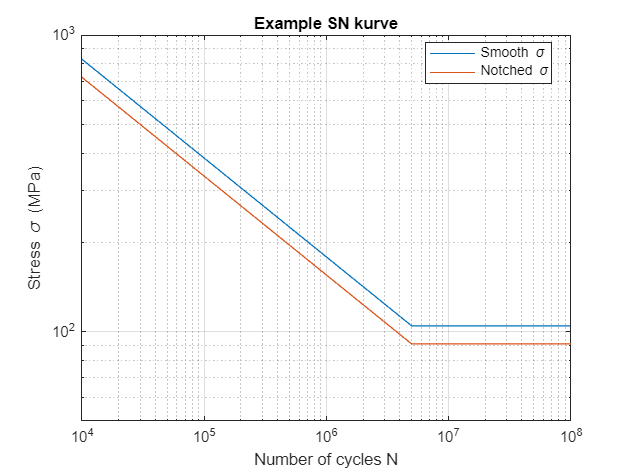



m1 = 3;
N_start = 1e4;
N_D = 5e6;
N_L = 1e8;

C1 =  super(sym('N'), N_D,sigma_R_smooth,m1);
S_start =   super(C1,N_start,sym('S'),m1);
S_D =  super(C1,N_D,sym('S'),m1);


S_smooths = [S_start,sigma_R_smooth, S_D];
N_smooths = [N_start, N_D, N_L];


loglog(N_smooths, S_smooths, DisplayName="Smooth \sigma")
hold on
% scatter(N_smooth,sigma_R_smooth, "filled", DisplayName="Knee point")

C1_notch =  super(sym('N'), N_D,sigma_R_notched,m1);
S_start =   super(C1_notch,N_start,sym('S'),m1);
S_D =  super(C1_notch,N_D,sym('S'),m1);
S_smooths = [S_start,sigma_R_notched, S_D];
N_smooths = [N_start, N_D, N_L];
loglog(N_smooths, S_smooths, DisplayName="Notched \sigma")
title('Example SN kurve')
xlabel('Number of cycles N')
ylabel('Stress \sigma (MPa)')
ylim([50, 1000])
legend('location', 'best')
grid("on")

hold off